# **Prob2. Generate trajectory using ScrewTrajectory.m**

Using matlab generate trajectory by "ScrewTrajectory,m" in joint space and plot in CoppeliaSim.

- Generate trajectory in SE(3) matrix.

- Show output together with your MATLAB code.

- Plot the motion of Indy 7 manipulator by CoppeliaSim.

## First import the matlab library.

% 20190348 Jungill Kang
addpath('..\mr')
clear; clc;

## Observe ScrewTrajectory.m

## Now create code which create joint trajectory using 3rd order polynomial time scaling.

Starts from initial state to final state.

Use this properties below.

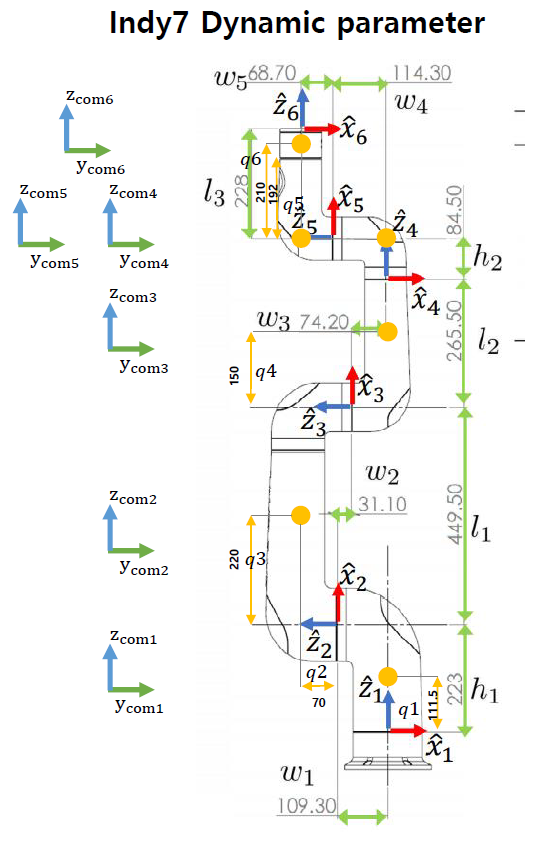

[Initial state]

with all joint variables set to zero.

Xstart = 

[[1 ,0, 0, 0];

[0, 1, 0, -W1+W2+W3-W4-W5]; 

[0, 0, 1, H1+L1+L2+H2+L3];

[0, 0, 0, 1]];

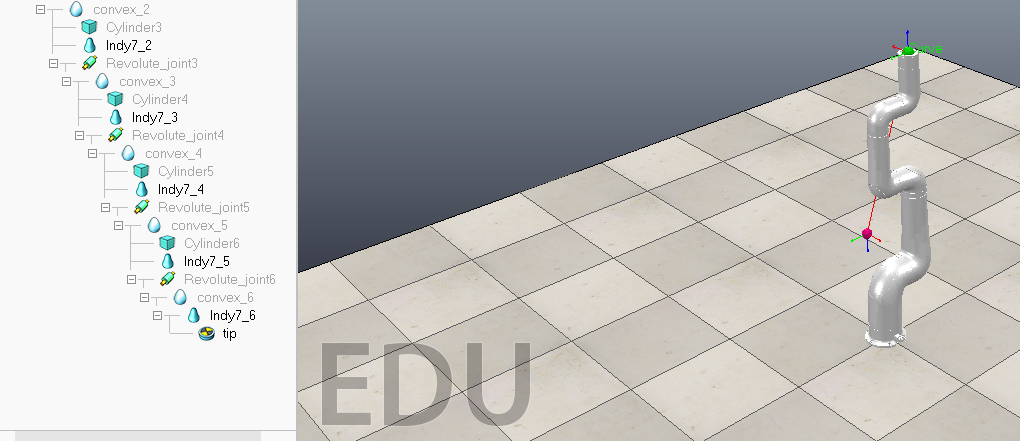

[Final state]

with theta 2 = pi/2.

Xend = 

[[0, 0, -1, -L1-L2-H2-L3];

[0, 1, 0, -W1+W2+W3-W4-W5];

[1, 0, 0, H1];

[0, 0, 0, 1]];

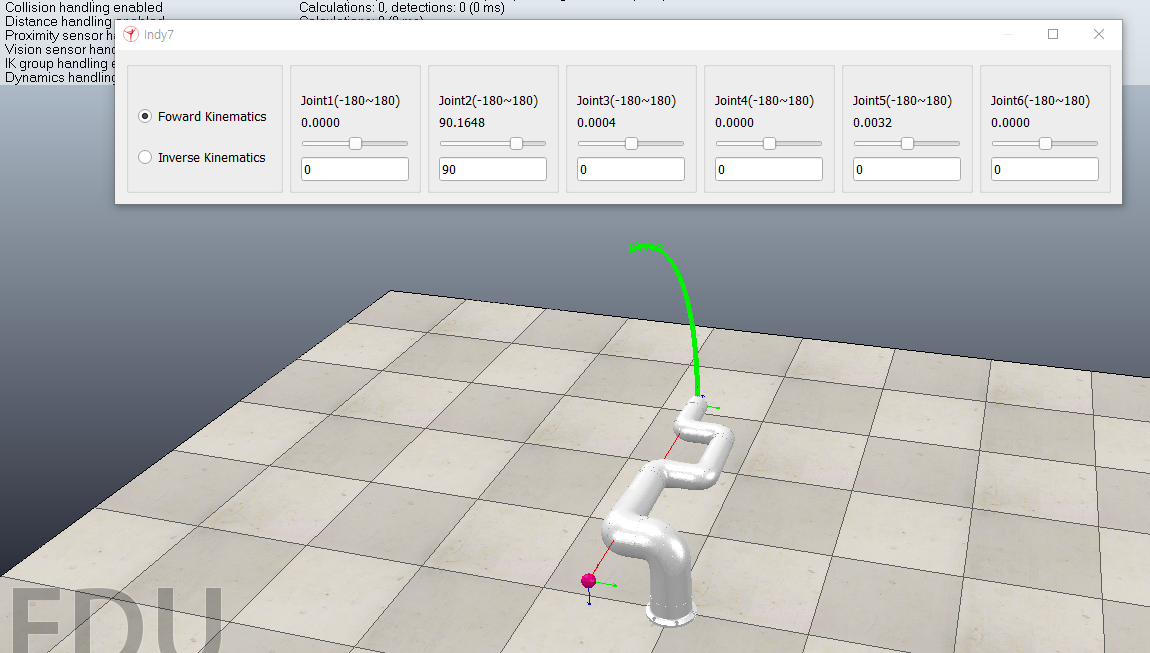

Implement with code.

And find the spatial screw axis.

These parameters are from above image.

clear; clc;

% length
L1 = 449.5 * 0.001;
L2 = 265.5 * 0.001;
L3 = 228 * 0.001;
H1 = 223 * 0.001;
H2 = 84.5 * 0.001;
W1 = 109.3 * 0.001;
W2 = 31.1 * 0.001;
W3 = 74.2 * 0.001;
W4 = 114.3 * 0.001;
W5 = 68.7 * 0.001;
q1 = 111.5 * 0.001;
q2 = 70 * 0.001;
q3 = 220 * 0.001;
q4 = 150 * 0.001;
q5 = 192 * 0.001;
q6 = 210 * 0.001;

% S list, screw axis list
Slist = [[0 ; 0; 1; 0; 0; 0;], ...
        [0; -1; 0; H1; 0; 0;], ...
        [0; -1; 0; L1+H1; 0; 0;], ...
        [0 ; 0; 1; -W1+W2+W3; 0; 0;], ...
        [0; -1; 0; H1+H2+L1+L2; 0; 0;], ...
        [0 ; 0; 1; -W1+W2+W3-W4-W5; 0; 0;]];

% Trajectory making
Xstart = [[1 ,0, 0, 0]; [0, 1, 0, -W1+W2+W3-W4-W5]; [0, 0, 1, H1+L1+L2+H2+L3]; [0, 0, 0, 1]];

thetaend = [0; pi/2; 0; 0; 0; 0];
Xend = FKinSpace(Xstart,Slist,thetaend);

Tf = 4;
N = 100;
method = 3;
traj1 = ScrewTrajectory(Xstart, Xend, Tf, N, method)

traj1 = 1×100 cell 배열
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}  

traj2 = ScrewTrajectory(Xend, Xstart, Tf, N, method)

traj2 = 1×100 cell 배열
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}  

Here, traj1 is trajectroy starts from initial state to final state, and traj2 is trajectory for going back from final state to initial state.

We need to change the SE(3) matrix to joint variables.

For traj1

traj1thetalist = zeros(6, N);

% for trajectory making
M0 = Xstart;
thetalist0 = [0; 0; 0; 0; 0; 0;];
eomg = 0.001;
ev = 0.0001;

for i = 1:N
    % create trajectory using IKinSpace.m
    T = cell2mat(traj1(i));
    
    [thetalist, success] = IKinSpace(Slist, M0, T, thetalist0, eomg, ev);

    if success == 1
        % update initial guess < -- previous step's result
        for j = 1:6
            % error occurs, spin more than 2 * pi which means redundant
            % spins.
            if abs(thetalist0(j) - thetalist(j)) > 2 * pi
                if thetalist(j) < 0
                    % modular operation
                    thetalist0(j) = -1*mod(-thetalist(j), 2 * pi);
                    % ex) if the result of angle is 359 degree
                    % you can consider to spin -1 degree which is same.
                    % which can avoid singular error.
                    if thetalist0(j) < -pi
                        thetalist0(j)  = thetalist0(j) + 2*pi;
                    end
                else
                    thetalist0(j) = 1*mod(thetalist(j), 2 * pi);
                    if thetalist0(j) > pi
                        thetalist0(j)  = thetalist0(j) - 2*pi;
                    end
                end
            else
                thetalist0(j) = thetalist(j);
            end
        end
        
        traj1thetalist(:, i) = thetalist0;
    else
        traj1thetalist(:, i) = thetalist0;
        disp(i);
    end
end

For traj2

traj2thetalist = zeros(6, N);

M0 = Xstart;
% use thetalist from previous results.
eomg = 0.001;
ev = 0.0001;

% use Slist from previous results

for i = 1:N
    T = cell2mat(traj2(i));
    
    [thetalist, success] = IKinSpace(Slist, M0, T, thetalist0, eomg, ev);
    
    if success == 1
        % update initial guess < -- previous step's result
        for j = 1:6
            % error occurs
            if abs(thetalist0(j) - thetalist(j)) > 2 * pi
                if thetalist(j) < 0
                    thetalist0(j) = -1*mod(-thetalist(j), 2 * pi);
                    if thetalist0(j) < -pi
                        thetalist0(j)  = thetalist0(j) + 2*pi;
                    end
                else
                    thetalist0(j) = 1*mod(thetalist(j), 2 * pi);
                    if thetalist0(j) > pi
                        thetalist0(j)  = thetalist0(j) - 2*pi;
                    end
                end
            else
                thetalist0(j) = thetalist(j);
            end
        end
        
        traj2thetalist(:, i) = thetalist0;
    else
        traj2thetalist(:, i) = thetalist0;
        disp(i);
    end  
end

And change the trajectory from above

sim=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1); % just in case, close all opened connections
clientID=sim.simxStart('127.0.0.1',19999,true,true,5000,5);

if (clientID>-1)
    disp('Connected to remote API server');
       
    %joints handles
    h = [0,0,0,0,0,0];
    for i=1:6
    [r, h(i)]= sim.simxGetObjectHandle(clientID, convertStringsToChars("Revolute_joint"+string(i)), sim.simx_opmode_blocking);
    end
    
    % n, duration has no big meaning
    n = 100;
    duration = 0.01;

    % You can change this code ------------------------------------------
    % traj1 init --> final
    % traj2 final --> init
    
    % repeat two trajectories
    joint_pos_mat1 = traj1thetalist;
    joint_pos_mat2 = traj2thetalist;
    

    while true
        for i=1:n
            tstart = tic;
            for j=1:6
                sim.simxSetJointTargetPosition(clientID, h(j), joint_pos_mat1(j, i), sim.simx_opmode_streaming);
            end
            dt = toc(tstart);
            if dt<duration
                pause(duration-dt);
            end
        end
        pause(3);
        
        for i=1:n
            tstart = tic;
            for j=1:6
                sim.simxSetJointTargetPosition(clientID, h(j), joint_pos_mat2(j, i), sim.simx_opmode_streaming);
            end
            dt = toc(tstart);
            if dt<duration
                pause(duration-dt);
            end
        end
        pause(3);
    end
    % You can change this code ------------------------------------------
else
    disp('Failed connecting to remote API server');
end

Connected to remote API server


sim.delete(); % call the destructor!
disp('Program ended');

## Results

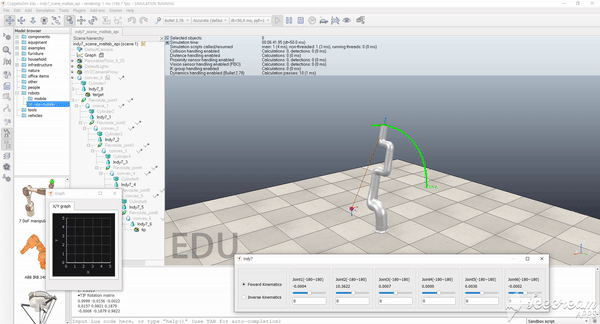

Since We use same initial & final orientation from prob1 the trajectory is same because screw axis for the prob2 is actually joint 2.